## Experimental Data

**Author:** Surabhi Joshi

## **Summary**

This script reads in some experimental data and performs exploratory initial statistical analysis to understand how each condition affects the metabolomics before running DFA. 

% download the experimental data and create two tables, one for each
% cancer cell line TU8902 and HCT116.
experimental_data_TU8902 = readtable('Barb Nelson Pos Table-20180410 - HL.xlsx', ...
'Sheet', 'TU8902');
experimental_data_HCT116 = readtable('Barb Nelson Pos Table-20180410 - HL.xlsx', ... 
 'Sheet',"HCT116");
% delete row 2 and column 2 from both tables
experimental_data_TU8902.transition = [];
experimental_data_HCT116.transition = [];

## **Create tables for averages and standard deviations. **

This here is going to take the averages and standard deviations from the original experimental data and fill two new tables with their values. Any NaN will be turned to 0 prior to finding the mean and standard deviations. 

Tabl_average_TU8902 = table_calc(experimental_data_TU8902, 'mean');
Tabl_std_TU8902 = table_calc(experimental_data_TU8902, 'stddev');
Tabl_average_HCT116 = table_calc(experimental_data_HCT116, 'mean');
Tabl_std_HCT116 = table_calc(experimental_data_HCT116, 'stddev');


## Create a corelation matrix and a following heatmap

Do this by first converting all the NaN values into 0 and then create a corelation matrix of the metabolites using an array of averages.  

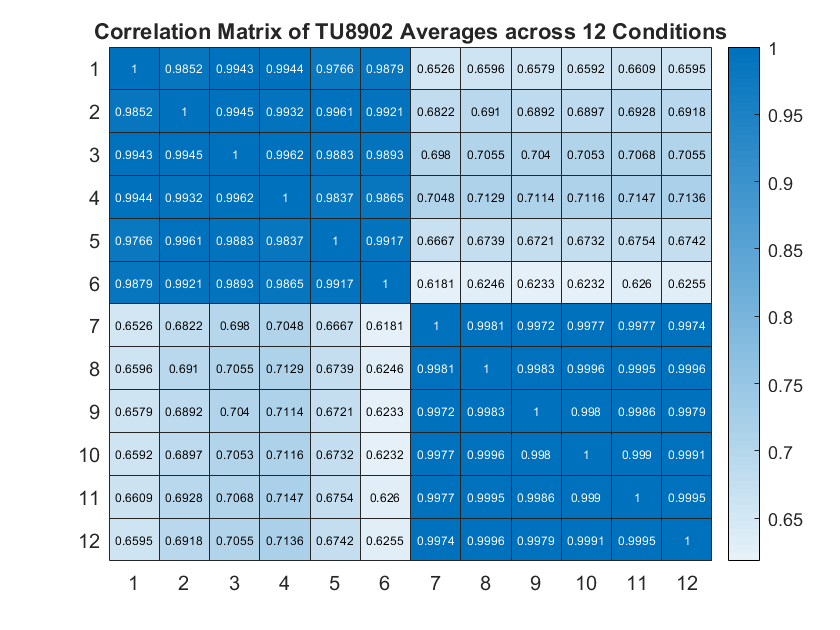

% create arrays from the tables above. 
mean_metabolomic_array_TU8902 = table2array(Tabl_average_TU8902(:,2:end));
std_metabolomic_array_TU8902 = table2array(Tabl_std_TU8902(:,2:end));

mean_metabolomic_array_HCT116 = table2array(Tabl_average_HCT116(:,2:end));
std_metabolomic_array_HCT116 = table2array(Tabl_std_HCT116(:,2:end));

%Convert all the NaN values to 0
mean_metabolomic_array_TU8902(isnan(mean_metabolomic_array_TU8902)) = 0;
mean_metabolomic_array_HCT116(isnan(mean_metabolomic_array_HCT116)) = 0;

%r matrix and its heatmap
averageCorrMat_TU8902 = corrcoef(mean_metabolomic_array_TU8902);
figure (1);
heatmap(averageCorrMat_TU8902);
title 'Correlation Matrix of TU8902 Averages across 12 Conditions';

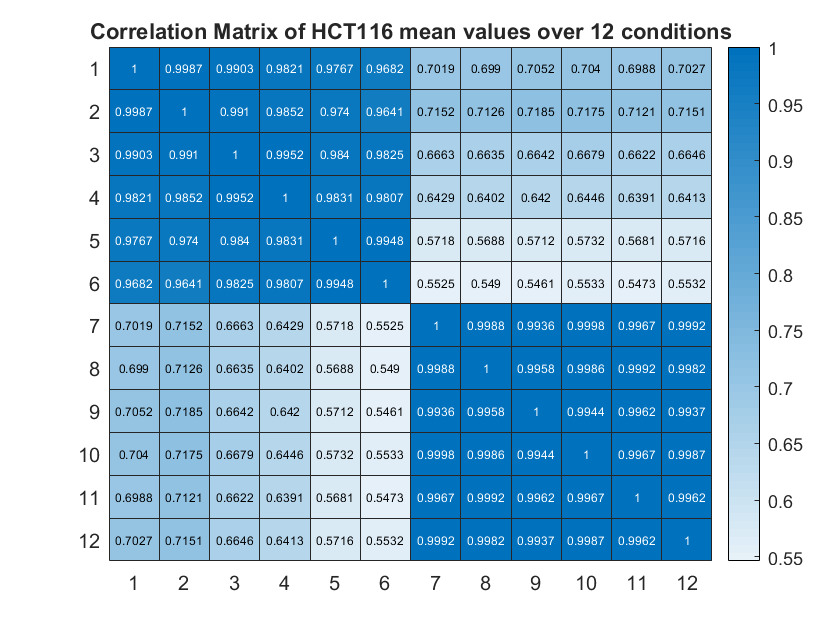


averageCorrMat_HCT116 = corrcoef(mean_metabolomic_array_HCT116);
figure (2);
heatmap(averageCorrMat_HCT116);
title 'Correlation Matrix of HCT116 mean values over 12 conditions';

## Create the correlation matrix, CV 

%CV matrix
CV_TU8902 = std_metabolomic_array_TU8902 ./ mean_metabolomic_array_TU8902;
CV_HCT116 = std_metabolomic_array_HCT116 ./ mean_metabolomic_array_HCT116;

%categorial array of the metabolites
metabolite_array = categorical(table2array(Tabl_average_TU8902(:,1)));

## Create heatmaps to visually understand the standard deviations and averages. 

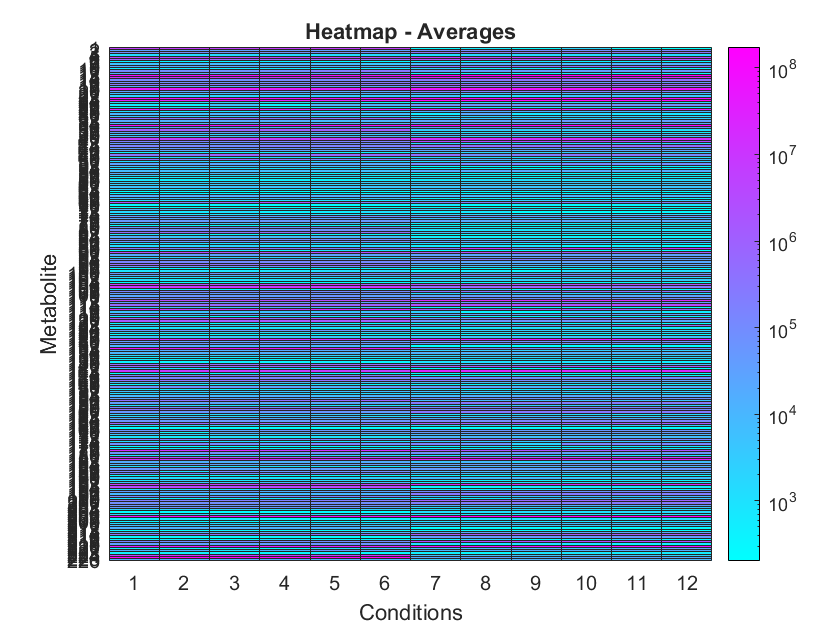

figure (3);
heatmap(mean_metabolomic_array_TU8902, 'ColorScaling', 'log');
xlabel('Conditions');
ylabel('Metabolite');
title('Heatmap - Averages');
colormap 'cool';


%an array of all NaN means for all conditions. These metabolites can be
%discarded from any further calculations. 
allNAN = [];
for i = 1:226
    if isnan(mean_metabolomic_array_TU8902(i,:))
        allNAN = [allNAN; metabolite_array(i)];
    end
end

From this figure, I propose that the allNAN to be discarded from any further calculations for teh TU8902 cancer cell line becase they do not have any corresponding data for any of the conditions and are just acting like 'noise'. 

## Scatterplots of the mean and standard deviations

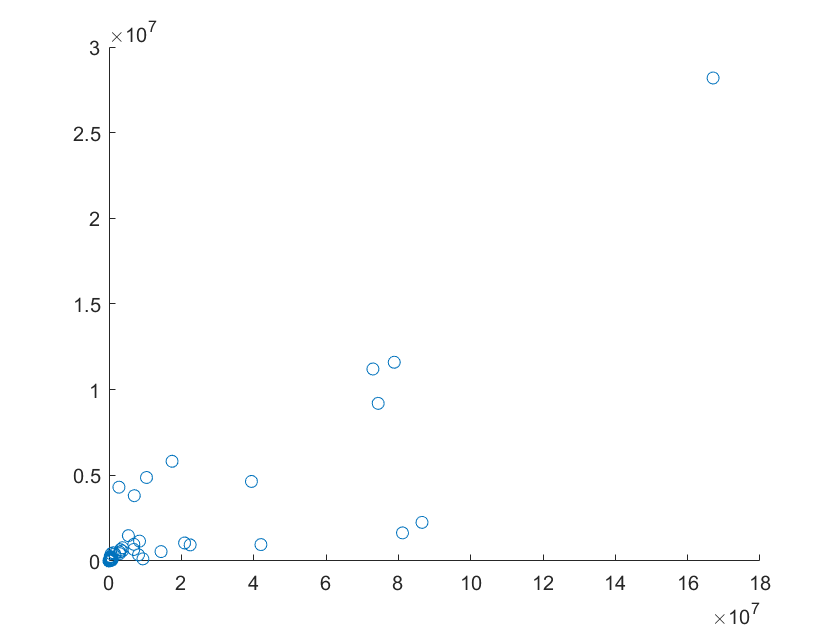

%scatterplots of mean and std
figure (2);
scatter(mean_metabolomic_array_TU8902(:,1), std_metabolomic_array_TU8902(:,1));

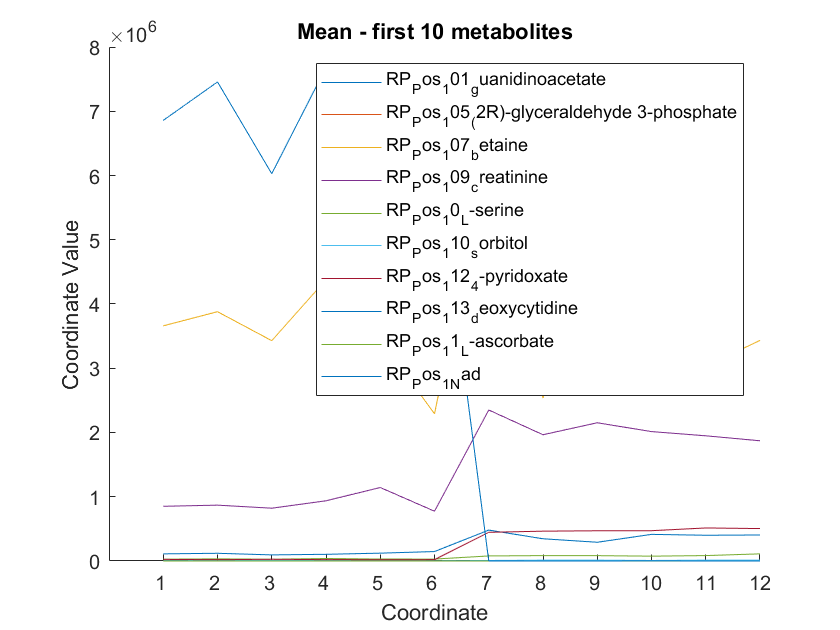


figure (3);
metabolite_array = categorical(table2array(Tabl_average_TU8902(:,1)));
parallelcoords(mean_metabolomic_array_TU8902((1:10),:), 'group', metabolite_array(1:10));
title('Mean - first 10 metabolites');

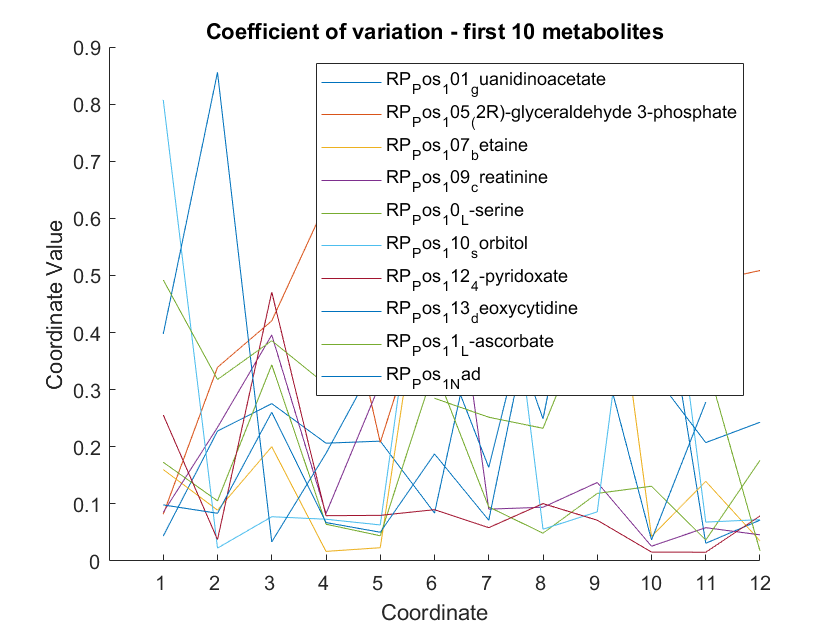


figure (4);
parallelcoords(CV_TU8902((1:10),:), 'group', metabolite_array(1:10));
title('Coefficient of variation - first 10 metabolites');

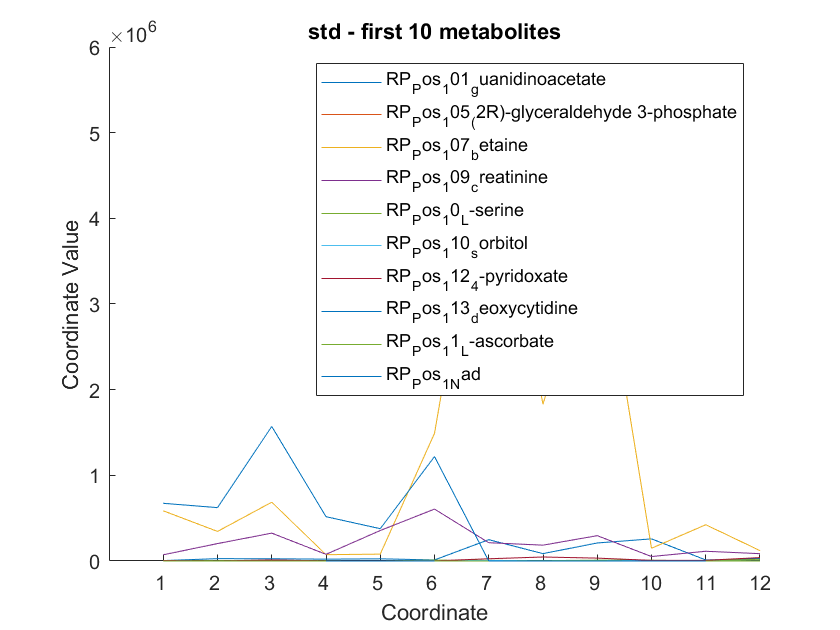


figure (5);
parallelcoords(std_metabolomic_array_TU8902((1:10),:), 'group', metabolite_array(1:10));
title('std - first 10 metabolites');

## Hisograms of the mean and standard deviations

%histograms of mean and std

